# Hills approach

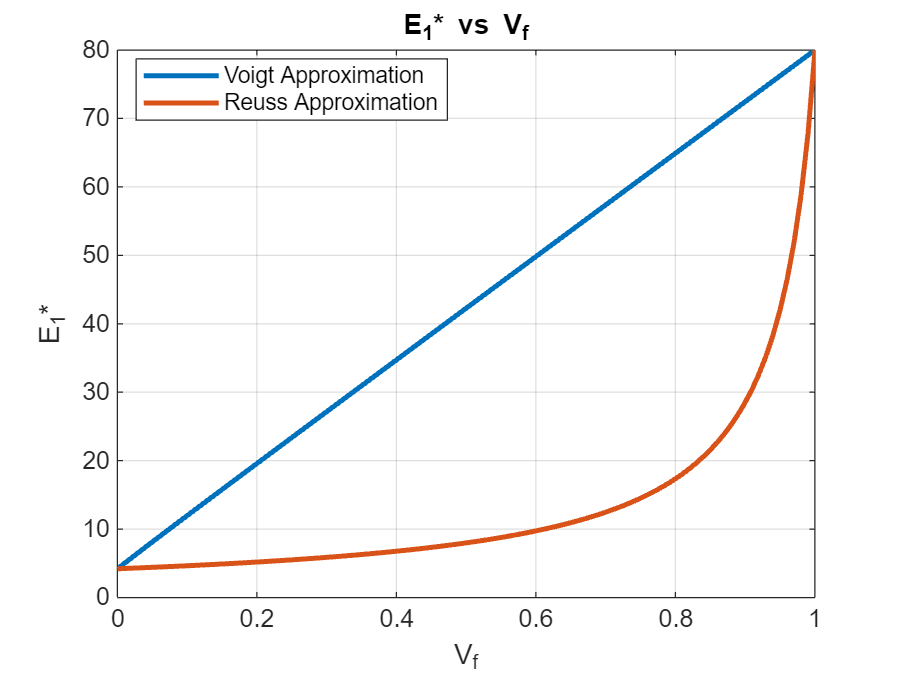

clc;clear;
syms Vf
Vf_val = linspace(0,1,101);

E_f = 80;
G_f = 33.33;
v_f = 0.2;
a1_f = 4.9;
a2_f = 4.9;
S_f = [1/E_f, -v_f/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, 1/E_f, -v_f/E_f, 0, 0, 0;
       -v_f/E_f, -v_f/E_f, 1/E_f, 0, 0, 0;
       0, 0, 0, 1/G_f, 0, 0;
       0, 0, 0, 0, 1/G_f, 0;
       0, 0, 0, 0, 0, 1/G_f;];
C_f = inv(S_f);

E_m = 4.2;
v_m = 0.34;
a_m = 45;
G_m = E_m/(2*(1+v_m));
S_m = [1/E_m, -v_m/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, 1/E_m, -v_m/E_m, 0, 0, 0;
       -v_m/E_m, -v_m/E_m, 1/E_m, 0, 0, 0;
       0, 0, 0, 1/G_m, 0, 0;
       0, 0, 0, 0, 1/G_m, 0;
       0, 0, 0, 0, 0, 1/G_m;];
C_m = inv(S_m);

%voight approximaation
C_c_v = C_m.*(1-Vf) + C_f.*Vf;
S_c_v = inv(C_c_v);

%Reuss approximation
S_c_r = S_m*(1-Vf) + S_f*Vf;

%E1
E1_c_v = 1/S_c_v(1,1);
E1_c_v_val = subs(E1_c_v,Vf_val);
E1_c_r = 1/S_c_r(1,1);
E1_c_r_val = subs(E1_c_r,Vf_val);

%E2
E2_c_v = 1/S_c_v(2,2);
E2_c_v_val = subs(E2_c_v,Vf_val);
E2_c_r = 1/S_c_r(2,2);
E2_c_r_val = subs(E2_c_r,Vf_val);

%v12
v12_c_v = -S_c_v(1,2)*E1_c_v;
v12_c_v_val = subs(v12_c_v,Vf_val);
v12_c_r = -S_c_r(2,1)*E2_c_r;
v12_c_r_val = subs(v12_c_r,Vf_val);

%v23
v23_c_v = -S_c_v(2,3)*E2_c_v;
v23_c_v_val = subs(v23_c_v,Vf_val);
v23_c_r = -S_c_r(3,2)*E2_c_r;
v23_c_r_val = subs(v23_c_r,Vf_val);

%G12
G12_c_v = 1/S_c_v(5,5);
G12_c_v_val = subs(G12_c_v,Vf_val);
G12_c_r = 1/S_c_r(5,5);
G12_c_r_val = subs(G12_c_r,Vf_val);

%G23
G23_c_v = 1/S_c_v(4,4);
G23_c_v_val = subs(G23_c_v,Vf_val);
G23_c_r = 1/S_c_r(4,4);
G23_c_r_val = subs(G23_c_r,Vf_val);

%plot
%E1
plot(Vf_val,E1_c_v_val,'LineWidth',2);
hold on;
plot(Vf_val,E1_c_r_val,'LineWidth',2);
hold off;
title('E_1* vs V_f');
xlabel('V_f'); ylabel('E_1*');
legend('Voigt Approximation','Reuss Approximation','Location','best');
grid on;

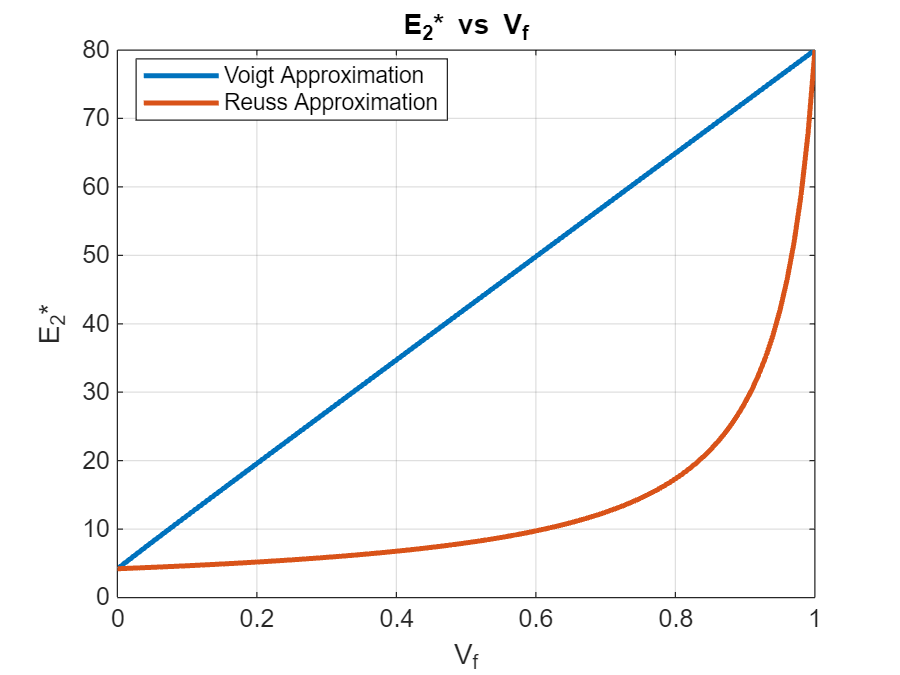


%E2
plot(Vf_val,E2_c_v_val,'LineWidth',2);
hold on;
plot(Vf_val,E2_c_r_val,'LineWidth',2);
hold off;
title('E_2* vs V_f');
xlabel('V_f'); ylabel('E_2*');
legend('Voigt Approximation','Reuss Approximation','Location','best');
grid on;

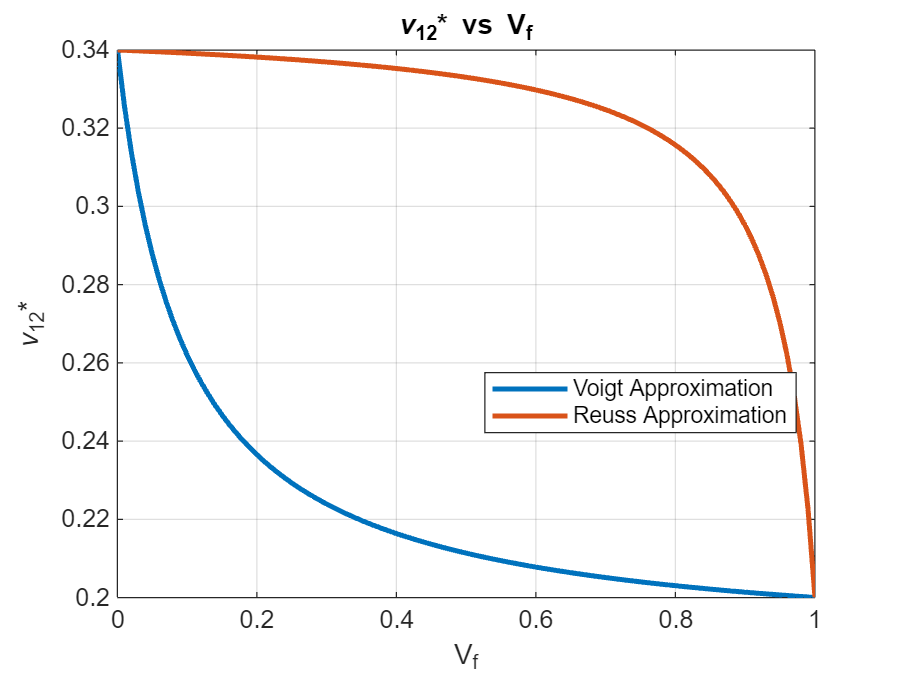


%v12
plot(Vf_val,v12_c_v_val,'LineWidth',2);
hold on;
plot(Vf_val,v12_c_r_val,'LineWidth',2);
hold off;
title('\nu_{12}* vs V_f');
xlabel('V_f'); ylabel('\nu_{12}*');
legend('Voigt Approximation','Reuss Approximation','Location','best');
grid on;

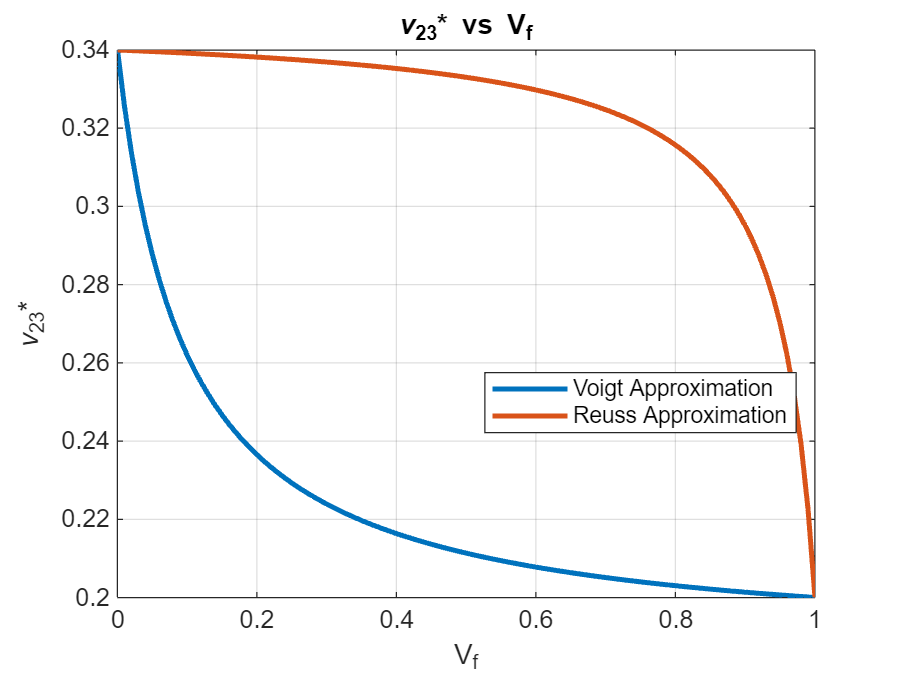


%v23
plot(Vf_val,v23_c_v_val,'LineWidth',2);
hold on;
plot(Vf_val,v23_c_r_val,'LineWidth',2);
hold off;
title('\nu_{23}* vs V_f');
xlabel('V_f'); ylabel('\nu_{23}*');
legend('Voigt Approximation','Reuss Approximation','Location','best');
grid on;

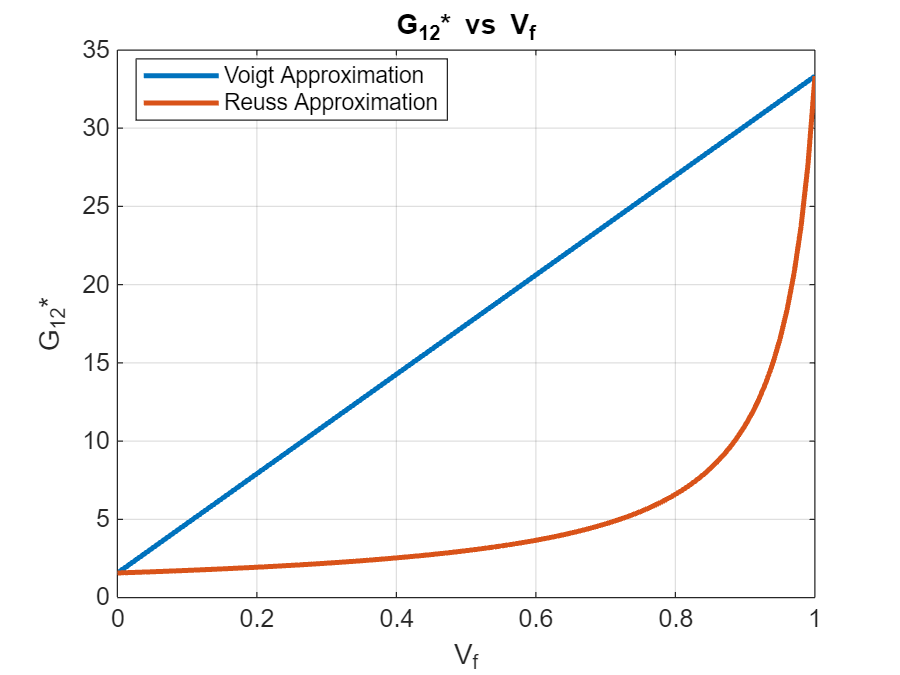


%G12
plot(Vf_val,G12_c_v_val,'LineWidth',2);
hold on;
plot(Vf_val,G12_c_r_val,'LineWidth',2);
hold off;
title('G_{12}* vs V_f');
xlabel('V_f'); ylabel('G_{12}*');
legend('Voigt Approximation','Reuss Approximation','Location','best');
grid on;

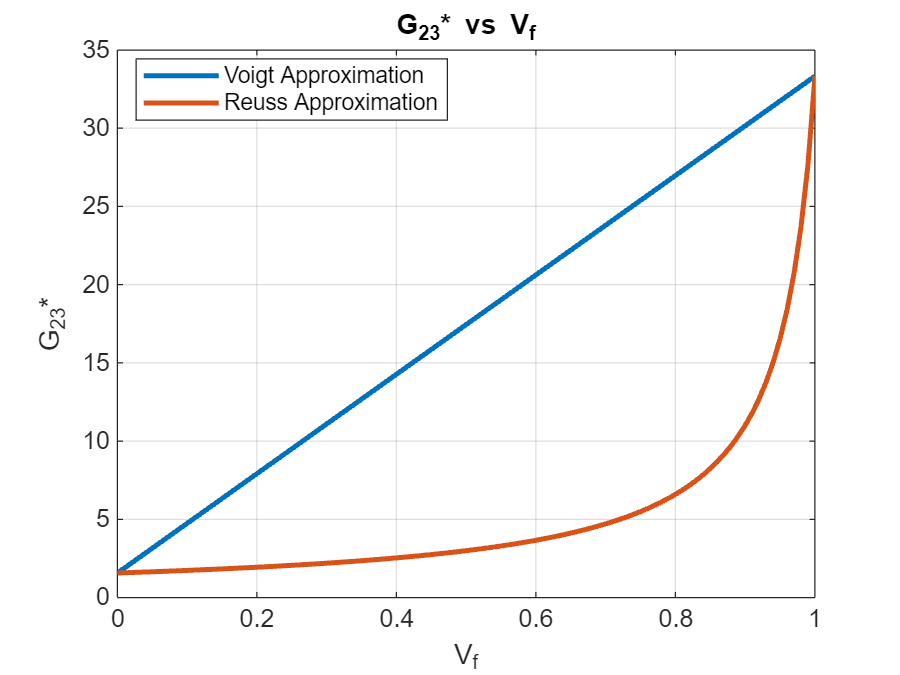


%G23
plot(Vf_val,G23_c_v_val,'LineWidth',2);
hold on;
plot(Vf_val,G23_c_r_val,'LineWidth',2);
hold off;
title('G_{23}* vs V_f');
xlabel('V_f'); ylabel('G_{23}*');
legend('Voigt Approximation','Reuss Approximation','Location','best');
grid on;